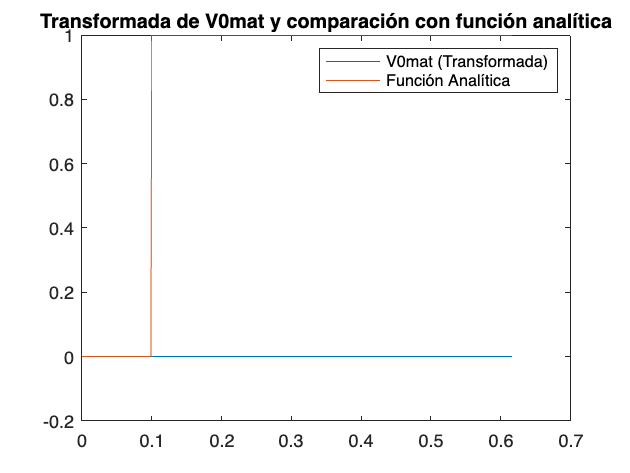

% Mario Sánchez Gutiérrez
% Código combinado de la Línea de Transmisión y Laplace Discreta

clc, clear all

%% Code 1: Transmission Line Calculations (V0 and VL)

% Datos de la Línea
muestras = 500; % Discretización (0.1 a 10 kHz)
long = 100;
yg = 1*exp(8);
yL = 1*exp(-8);
L = 0.5;
C = 0.1;
m = 0.1;
k = 10000;
delta = k/muestras;
vector_frecuencia = m:delta:k; % Vector de 1 x 500 (matriz)
w_fund = 377.0; % Frecuencia fundamental (60 Hz)
w = 2*pi*vector_frecuencia;
s = complex(w); % Frecuencia en número complejo

vg = s./((s.^2)+(w_fund.^2)); % Voltaje por Laplace
Rg = 1/yg; % Resistencia del generador

Ig = vg/Rg; % Corriente del generador
IL = zeros(1, 500); % Sin carga al final de la línea

% Parámetros de la Línea
r = 10;
jwl = w*L;
z = complex(r,jwl); % Impedancia

g = 0;
jwc = w*C;
y = complex(g,jwc); % Admittancia

gama = sqrt(z.*y); % Gama
y0 = sqrt(y./z); % Admittancia característica
z0 = sqrt(z./y); % Impedancia característica

d = long*gama; % Longitud eléctrica

% Matriz ABCD
A = cosh(d);
B = z0.*sinh(d);
C = y0.*sinh(d);
D = A;

% Agregar yg y yL al circuito
Yss = -(B.^-1).*A + yg;
Ysr = (B.^-1);
Yrs = C - D.*(B.^-1).*A;
Yrr = D.*(B.^-1) + yL;

% Cálculo de V0 y VL
for n=1:muestras
    Ybus = [Yss(1,n) Ysr(1,n); Yrs(1,n) Yrr(1,n)];
    Imat = [Ig(1,n); IL(1,n)];
    Vmat = (Ybus^-1)*Imat;
    V0mat(1,n) = Vmat(1,1); % Voltaje en el generador
    VLmat(1,n) = Vmat(2,1); % Voltaje en la carga
end

%% Code 2: Laplace Transform (Numerical)

% Parámetros de Simulación
T = 0.65;  % Tiempo total de simulación
N = muestras; % Número de puntos de muestreo
error = 0.0001;
dw = pi/T;  % Paso en frecuencia
dt = T/N;  % Paso de tiempo
c = log(N^2)/T;  % Coeficiente de amortiguamiento

% Vectores de tiempo y frecuencia
t = dt*(0:N-1);
n = 0:N-1;
m = 1:2:2*N;
s_freq = c + 1i*m*dw; % Valores complejos en frecuencia
Cn = (N*2*dw/pi)*exp(c*dt+1i*n*pi/N);

% Transformar V0mat y VLmat usando DNLT
V0_dnl = DNLT(V0mat, c, dt);
VL_dnl = DNLT(VLmat, c, dt);

% Analytic Time-Domain Function
tau = 0.1;
ft = [zeros(1,find(t >= tau,1)-1) ones(1,N-find(t >= tau,1)+1)];

% Graficar Resultados para V0 y VL
Np = floor(N*0.95);
figure;
plot(t(1:Np),real(V0_dnl(1:Np)),t(1:Np),ft(1:Np));
title('Transformada de V0mat y comparación con función analítica');
legend('V0mat (Transformada)', 'Función Analítica');

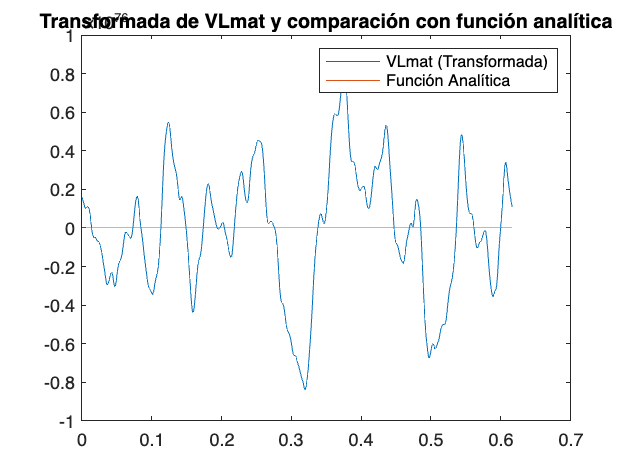


figure;
plot(t(1:Np),real(VL_dnl(1:Np)),t(1:Np),ft(1:Np));
title('Transformada de VLmat y comparación con función analítica');
legend('VLmat (Transformada)', 'Función Analítica');


%% DNLT Function

function y = DNLT(ftd, c, dt)
    % DNLT: Calcula la transformada de Laplace discreta de una señal.
    % Entrada:
    %   ftd: Vector de valores de la señal en el dominio del tiempo.
    %   c: Factor de amortiguamiento.
    %   dt: Paso de tiempo.
    % Salida:
    %   y: Transformada de Laplace discreta de la señal.

    % Obtener la longitud de la señal
    order = size(ftd);
    N = order(2);

    % Crear un vector de índices
    n = 0:N-1;

    % Calcular la exponencial compleja
    exp1 = exp(-c*dt - 1i*pi/N).^n;

    % Multiplicar la señal por la exponencial
    fw = ftd .* exp1;

    % Aplicar la transformada de Fourier discreta
    y = dt * fft(fw);
end